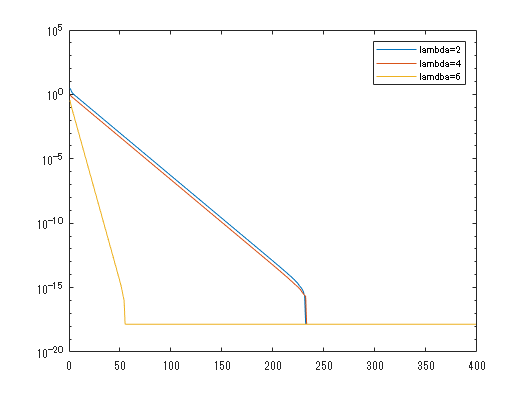

A = [3, 0.5;
    0.5, 1;];
mu = [1; 
    2;];
w0 = [3; -1];
wt = w0;
phi = @(w) (w-mu)'*A*(w-mu);
nab_phi = @(w) A*(w-mu);
ST = @(q, mu) SoftThreshold(q,mu);
lr = max(eig(2*A));
lambda = [2,4,6];
g = lr;
loop = 400;
w_history = zeros([2,loop,length(lambda)],"double");
w_prep_norm_history = zeros([2,loop,length(lambda)],"double");
w_norm_history = zeros(size(loop,length(lambda)));
for l = 1:length(lambda)
for t = 1:loop
    w_history(:,t,l) = wt;
    mu_step = wt - nab_phi(wt)./ g;
    wt = ST(l/g, mu_step);
end

w_prep_norm_history(1,:,l) = (w_history(1,:,l) - w_history(1,loop,l) + 1e-18.*ones(size(w_history(1,:,l))));% 1e-18 : To avoid log(0)
w_prep_norm_history(2,:,l) = (w_history(2,:,l) - w_history(2,loop,l) + 1e-18.*ones(size(w_history(2,:,l))));% 1e-18 : To avoid log(0)

for t = 1:loop
    w_norm_history(t,l) = norm(w_prep_norm_history(:,t,l),2);
end
end
semilogy(w_norm_history(1:loop-1,1));
hold on
semilogy(w_norm_history(1:loop-1,2));
semilogy(w_norm_history(1:loop-1,3));
legend("lambda=2","lambda=4","lamdba=6")
hold off

cvx_check

index = 3;
%cvx model
cvx_begin quiet
    variables w(2)  
    minimize ((w-mu)' * A * (w-mu) + lambda(index) * norm(w, 1))
cvx_end
w

w =     0.3333
    0.0000


w_history(:,loop,index)

ans =     0.3333
         0


function [result] = SoftThreshold(q, mu)
result = zeros(size(mu));
for i = 1:length(mu)
    if mu(i) > q
        result(i) = mu(i)-q;
    elseif abs(mu(i)) <= q
        result(i) = 0;
    elseif mu(i) < -q
        result(i) = mu(i) + q;
    else
        fprintf("error");
        result = 0;
    end
end
end